# Primary Analysis of Three Displays

## Preparation

rift = RiftSim(2)

obj =   RiftSim with properties:

      dataspec: []
        ramp_r: []
        ramp_g: []
        ramp_b: []
         lut_x: []
           lut: []
            sc: 0.0400
        spec_r: []
        spec_g: []
        spec_b: []
     classpath: 'C:\Users\Wuchihlei\Documents\GitHub\MIS_acquire\@RiftSim'
    gamma_srgb: []
         vec_r: []
         vec_g: []
         vec_b: []
          HIMS: []
      vec_file: 'OL490_vec_HIMS2.mat'


rift =   RiftSim with properties:

      dataspec: [1024×401 double]
        ramp_r: [256×401 double]
        ramp_g: [256×401 double]
        ramp_b: [256×401 double]
         lut_x: [18×1 double]
           lut: [18×3 double]
            sc: 0.0400
        spec_r: [1×401 double]
        spec_g: [1×401 double]
        spec_b: [1×401 double]
     classpath: 'C:\Users\Wuchihlei\Documents\GitHub\MIS_acquire\@RiftSim'
    gamma_srgb: []
         vec_r: []
         vec_g: []
         vec_b: []
          HIMS: []
      vec_file: 'OL490_vec_HIMS2.mat'


hp = HPZ24xSim(2)

obj =   HPZ24xSim with properties:

            sc: 0.0400
        spec_r: []
        spec_g: []
        spec_b: []
     classpath: 'C:\Users\Wuchihlei\Documents\GitHub\MIS_acquire\@HPZ24xSim'
    gamma_srgb: []
         vec_r: []
         vec_g: []
         vec_b: []
          HIMS: []
      vec_file: 'OL490_vec_HIMS2.mat'


hp =   HPZ24xSim with properties:

            sc: 0.0400
        spec_r: [1×401 double]
        spec_g: [1×401 double]
        spec_b: [1×401 double]
     classpath: 'C:\Users\Wuchihlei\Documents\GitHub\MIS_acquire\@HPZ24xSim'
    gamma_srgb: []
         vec_r: []
         vec_g: []
         vec_b: []
          HIMS: []
      vec_file: 'OL490_vec_HIMS2.mat'


nec = NECPA271Sim(2)

obj =   NECPA271Sim with properties:

            sc: 0.0400
        spec_r: []
        spec_g: []
        spec_b: []
     classpath: 'C:\Users\Wuchihlei\Documents\GitHub\MIS_acquire\@NECPA271Sim'
    gamma_srgb: []
         vec_r: []
         vec_g: []
         vec_b: []
          HIMS: []
      vec_file: 'OL490_vec_HIMS2.mat'


nec =   NECPA271Sim with properties:

            sc: 0.0400
        spec_r: [1×401 double]
        spec_g: [1×401 double]
        spec_b: [1×401 double]
     classpath: 'C:\Users\Wuchihlei\Documents\GitHub\MIS_acquire\@NECPA271Sim'
    gamma_srgb: []
         vec_r: []
         vec_g: []
         vec_b: []
          HIMS: []
      vec_file: 'OL490_vec_HIMS2.mat'


#### Spectral comparison of the red, green, and blue primary colors of the simulated displays

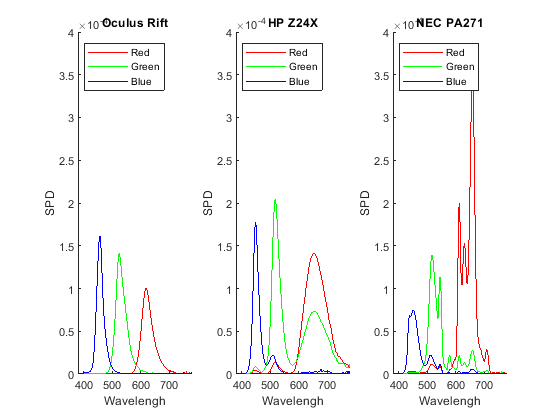

clf
subplot(1,3,1)
rift.show_spectra
xlabel('Wavelengh')
ylabel('SPD')
title('Oculus Rift')

subplot(1,3,2)
hp.show_spectra
xlabel('Wavelengh')
ylabel('SPD')
title('HP Z24X')

subplot(1,3,3)
nec.show_spectra
xlabel('Wavelengh')
ylabel('SPD')
title('NEC PA271')

saveas(gcf,'compare3spectra.png')

#### Color gamuts of the three displays to be simulated

srgb = [0.64 0.33; 0.3 0.6 ; 0.15 0.06];
adobergb = [0.64 0.33; 0.21 0.71 ; 0.15 0.06];
p3 = [0.68 0.32; 0.265 0.69 ; 0.15 0.06];
rec2020 = [0.708 0.292; 0.170 0.797 ; 0.131 0.046];

cc = ColorConversionClass;

clf
hold on


plot(srgb([1 2 3 1],1),srgb([1 2 3 1],2),':')
plot(adobergb([1 2 3 1],1),adobergb([1 2 3 1],2),':')
plot(p3([1 2 3 1],1),p3([1 2 3 1],2),':')
%plot(rec2020([1 2 3 1],1),rec2020([1 2 3 1],2),':')

dp = rift;
XYZ_r = cc.spd2XYZ(dp.spec_r(1:10:end)');
XYZ_g = cc.spd2XYZ(dp.spec_g(1:10:end)');
XYZ_b = cc.spd2XYZ(dp.spec_b(1:10:end)');

xyz_r = XYZ_r / sum(XYZ_r);
xyz_g = XYZ_g / sum(XYZ_g);
xyz_b = XYZ_b / sum(XYZ_b);

plot([xyz_r(1) xyz_g(1) xyz_b(1) xyz_r(1)],[xyz_r(2) xyz_g(2) xyz_b(2) xyz_r(2)],'o')


dp = nec;
XYZ_r = cc.spd2XYZ(dp.spec_r(1:10:end)');
XYZ_g = cc.spd2XYZ(dp.spec_g(1:10:end)');
XYZ_b = cc.spd2XYZ(dp.spec_b(1:10:end)');

xyz_r = XYZ_r / sum(XYZ_r);
xyz_g = XYZ_g / sum(XYZ_g);
xyz_b = XYZ_b / sum(XYZ_b);

plot([xyz_r(1) xyz_g(1) xyz_b(1) xyz_r(1)],[xyz_r(2) xyz_g(2) xyz_b(2) xyz_r(2)],'o')

dp = hp;
XYZ_r = cc.spd2XYZ(dp.spec_r(1:10:end)');
XYZ_g = cc.spd2XYZ(dp.spec_g(1:10:end)');
XYZ_b = cc.spd2XYZ(dp.spec_b(1:10:end)');

xyz_r = XYZ_r / sum(XYZ_r);
xyz_g = XYZ_g / sum(XYZ_g);
xyz_b = XYZ_b / sum(XYZ_b);

plot([xyz_r(1) xyz_g(1) xyz_b(1) xyz_r(1)],[xyz_r(2) xyz_g(2) xyz_b(2) xyz_r(2)],'o')



axis equal
xlabel('CIE x')
ylabel('CIE y')


leg = legend('sRGB','AdobeRGB','DCI-P3','Oculus','NEC','HP')

leg =   Legend (sRGB, AdobeRGB, DCI-P3, Oculus, NEC, HP) with properties:

         String: {'sRGB'  'AdobeRGB'  'DCI-P3'  'Oculus'  'NEC'  'HP'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.6863 0.6559 0.2000 0.2440]
          Units: 'normalized'

  Show all properties


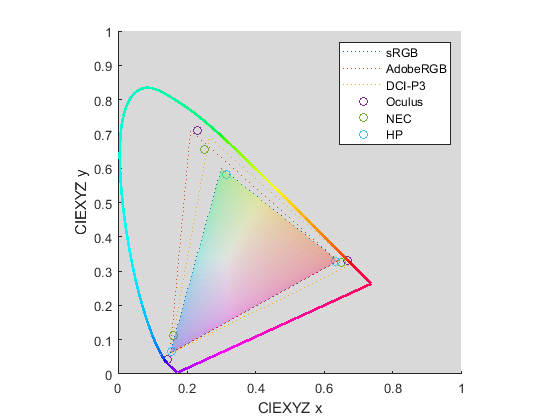

set(leg,'AutoUpdate','off')

chromaticity = RGB_in_xyY;